Syms

theta2 = sym('theta_2');
theta3 = sym('theta_3');
theta4 = sym('theta_4');
theta5 = sym('theta_5');
theta6 = sym('theta_6');
theta7 = sym('theta_7');
theta8 = sym('theta_8');

alpha = deg2rad(99.346);    % angle A-B-D
beta  = deg2rad(58.654);    % angle C-B-D
gamma = deg2rad(91.964);    % angle B-C-D
phi   = deg2rad(29.381);    % angle B-D-C

Assign Parameters

l1 = 80;   l2 = 12;    l3 = 55;    l4 = 48;
l5 = 165;  l6 = 55;    l7 = 48;    l8 = 165;
BC = 27;   BD = 55;    EG = 47;    FG = 27;
h8 = 85.147;   % link 8 ด้านบน

O2x = 0;       O2y = 0;
O4x = -49.891; O4y = 62.537;
O7x = 115.109; O7y = 62.537;

Formulate Equation

Ax = O2x + l2*cos(theta2); Ay = O2y + l2*sin(theta2);
Bx = O4x + l4*cos(theta4); By = O4y + l4*sin(theta4);
Fx = O7x + l7*cos(theta7); Fy = O7y + l7*sin(theta7);

Cx = Bx + BC*cos(theta3+pi-alpha-beta);   Cy = By + BC*sin(theta3+pi-alpha-beta);
Dx = Bx + BD*cos(theta3+pi-alpha);        Dy = By + BD*sin(theta3+pi-alpha);

Ex = Fx + l6*cos(theta6);                 Ey = Fy + l6*sin(theta6);
Gx = Fx + FG*cos(theta6-beta);            Gy = Fy + FG*sin(theta6-beta);

eq1 = Bx == Ax + l3*cos(theta3);
eq2 = By == Ay + l3*sin(theta3);

sol = solve([eq1 eq2],[theta3 theta4]);

Solutions

theta3_sol = sol.theta_3(1);
theta4_sol = sol.theta_4(1);

theta6_sol = theta3_sol+pi-alpha;   % link 6 // link 3
theta7_sol = theta4_sol;            % link 7 // link 4
theta5_sol = 0;                     % link 5 // O4-O7
theta8_sol = 0;                     % link 8 // O4-O7

Change all theta to theta2

S = @(s) subs(s,[theta3 theta4 theta5 theta6 theta7 theta8],...
                [theta3_sol theta4_sol theta5_sol theta6_sol theta7_sol theta8_sol]);

BxNew = S(Bx);   ByNew = S(By);
CxNew = S(Cx);   CyNew = S(Cy);
DxNew = S(Dx);   DyNew = S(Dy);
ExNew = S(Ex);   EyNew = S(Ey);
FxNew = S(Fx);   FyNew = S(Fy);
GxNew = S(Gx);   GyNew = S(Gy);
HxNew = CxNew;   HyNew = CyNew + h8;
IxNew = GxNew;   IyNew = GyNew + h8;

Plot

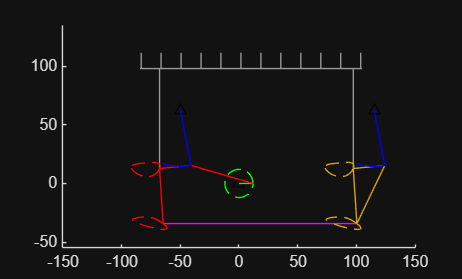

h_link2 = @(t) plot([O2x subs(Ax,t)],[O2y subs(Ay,t)],"-g");
h_link3 = @(t) plot([subs(Ax,t) subs(BxNew,t) subs(CxNew,t) subs(DxNew,t)],...
                    [subs(Ay,t) subs(ByNew,t) subs(CyNew,t) subs(DyNew,t)],...
                    "-r");
h_link4 = @(t) plot([O4x subs(BxNew,t)],[O4y subs(ByNew,t)],"-b");
h_link5 = @(t) plot([subs(DxNew,t) subs(ExNew,t)],[subs(DyNew,t) subs(EyNew,t)],"-m");
h_link6 = @(t) plot([subs(FxNew,t) subs(GxNew,t) subs(ExNew,t) subs(FxNew,t)],...
                    [subs(FyNew,t) subs(GyNew,t) subs(EyNew,t) subs(FyNew,t)],...
                    "-","Color",[0.85 0.65 0.0]);
h_link7 = @(t) plot([O7x subs(FxNew,t)],[O7y subs(FyNew,t)],"-b");
%link 8 teeth: 12 teeth, pitch 17, height 13.537 mm
%แต่ละ teeth สร้างเป็นเส้นที่จุด center
tooth_x = -15.663 + 17*(0:11);
tooth_h = 13.537;
top_x = [-16.663, repelem(tooth_x, 3), 172.337];
top_y = h8 + [0, repmat([0 tooth_h 0], 1, numel(tooth_x)), 0];

h_link8      = @(t) plot([subs(CxNew,t) subs(HxNew,t) subs(CxNew,t)+top_x subs(IxNew,t) subs(GxNew,t)],...
                    [subs(CyNew,t) subs(HyNew,t) subs(CyNew,t)+top_y subs(IyNew,t) subs(GyNew,t)],"-",...
                    "Color",[0.6 0.6 0.6]);

hold on
plot(O2x,O2y,"k^")
plot(O4x,O4y,"k^")
plot(O7x,O7y,"k^")

fanimator(h_link2)
fanimator(h_link3)
fanimator(h_link4)
fanimator(h_link5)
fanimator(h_link6)
fanimator(h_link7)
fanimator(h_link8)

theta_to_plot = deg2rad(0:5:360);
plot(subs(Ax,theta_to_plot),subs(Ay,theta_to_plot),"--g")
plot(subs(BxNew,theta_to_plot),subs(ByNew,theta_to_plot),"--b")
plot(subs(CxNew,theta_to_plot),subs(CyNew,theta_to_plot),"--r")
plot(subs(DxNew,theta_to_plot),subs(DyNew,theta_to_plot),"--r")
plot(subs(ExNew,theta_to_plot),subs(EyNew,theta_to_plot),"--","Color",[0.85 0.65 0.0])   % E on link 6
plot(subs(FxNew,theta_to_plot),subs(FyNew,theta_to_plot),"--b")
plot(subs(GxNew,theta_to_plot),subs(GyNew,theta_to_plot),"--","Color",[0.85 0.65 0.0])   % G on link 6
axis equal
hold off

Play

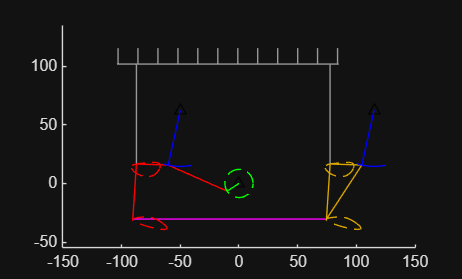

playAnimation